%% Instrument Classification Demo (robust, with consistent preprocessing)
clear; clc;
load("results/ml/instrument_classifier.mat");  % Mdl, mu, sigma, uniqueLabels

% -------- 1) 读取音频并重采样到 16 kHz --------
testFile = "demo_data/tuba_Gs3_1_mezzo-forte_normal.mp3"; % 换成任意测试文件
[x, fs] = audioread(testFile);
if size(x,2)>1, x = mean(x,2); end
if fs ~= 16000, x = resample(x, 16000, fs); end
fs = 16000;

% -------- 2) 与训练一致的预处理：去静音 + 幅度归一化 --------
x = trim_silence_local(x, 2048, 0.02);    % 与训练时一致的能量门限
x = x ./ max(1e-9, abs(x));               % 幅度归一化到 ~[-1,1]

% -------- 3) 对长音频做分段预测（更稳） --------
winDur = 0.8;              % 每段 0.8 s（与训练/合成长度一致）
hopDur = 0.4;              % 50% 重叠
wlen   = round(winDur*fs);
hop    = round(hopDur*fs);

N = numel(x);
starts = 1:hop:max(1, N-wlen+1);

Feats = [];
for s = starts
    seg = x(s:min(N, s+wlen-1));

    % 再做一次微弱静音截断，避免段尾/段首空白影响
    seg = trim_silence_local(seg, 1024, 0.02);
    if numel(seg) < round(0.3*fs)   % 太短的段跳过
        continue;
    end
    seg = seg ./ max(1e-9, abs(seg));

    % 提特征（用你项目中的函数）
    f = extract_features_local(seg, fs);
    Feats = [Feats; f]; %#ok<AGROW>
end

if isempty(Feats)
    error("有效语音段过少，无法提取特征。请换一段更清晰的音频再试。");
end

% 与训练一致的标准化
Feats = (Feats - mu) ./ (sigma + 1e-6);

% -------- 4) 分段预测 + 投票/置信度统计 --------
if isa(Mdl,'TreeBagger')
    [yp_batch, score] = predict(Mdl, Feats);           % yp_batch 是 cellstr
    yp_batch = categorical(yp_batch, cellstr(uniqueLabels));
else
    [yp_batch, score] = predict(Mdl, Feats);           % fitcecoc: categorical + score
end

% 多段投票：取众数作为最终类别
[finalLabel, ~, grp] = mode(yp_batch);
% 同时统计平均置信度（各类得分取均值）
meanScore = mean(score, 1);
[~, idxTop] = sort(meanScore, 'descend');

fprintf('\n=== Segment-wise Voting Result ===\n');


=== Segment-wise Voting Result ===


fprintf('Segments used: %d\n', numel(grp));

Segments used: 1


fprintf('Predicted Instrument (majority vote): %s\n', string(finalLabel));

Predicted Instrument (majority vote): tuba


fprintf('Top-3 by mean score:\n');

Top-3 by mean score:


for k = 1:min(3, numel(idxTop))
    fprintf('  %d) %s  (%.3f)\n', k, string(uniqueLabels(idxTop(k))), meanScore(idxTop(k)));
end

  1) tuba  (-0.000)
  2) cello  (-0.179)
  3) trombone  (-0.468)


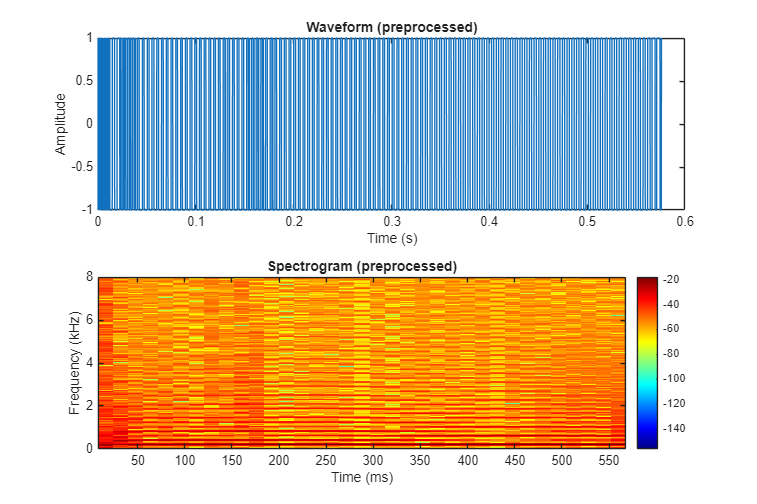


% -------- 5) 可视化 --------
figure('Name','Demo Visualization','Position',[100 100 900 600]);
subplot(2,1,1);
plot((0:numel(x)-1)/fs, x);
xlabel('Time (s)'); ylabel('Amplitude');
title("Waveform (preprocessed)");

subplot(2,1,2);
spectrogram(x, hann(512), 256, 1024, fs, 'yaxis');
title("Spectrogram (preprocessed)");
colormap jet;
colorbar;


%% ========== 本地辅助函数：与训练一致 ==========
function y = trim_silence_local(x, wlen, thr)
x = x(:);
w = hann(wlen,'periodic'); 
hop = round(wlen/2);
M = max(1,floor((numel(x)-wlen)/hop)+1);
e = zeros(M,1);
for i=1:M
    seg = x((i-1)*hop+1 : min(numel(x),(i-1)*hop+wlen));
    seg = seg .* w(1:numel(seg));
    e(i) = sum(seg.^2);
end
e = e ./ max(e+1e-12);
i1 = find(e>thr,1,'first'); if isempty(i1), i1=1; end
i2 = find(e>thr,1,'last');  if isempty(i2), i2=M; end
s = max(1,(i1-1)*hop+1);
t = min(numel(x),(i2-1)*hop+wlen);
y = x(s:t);
end


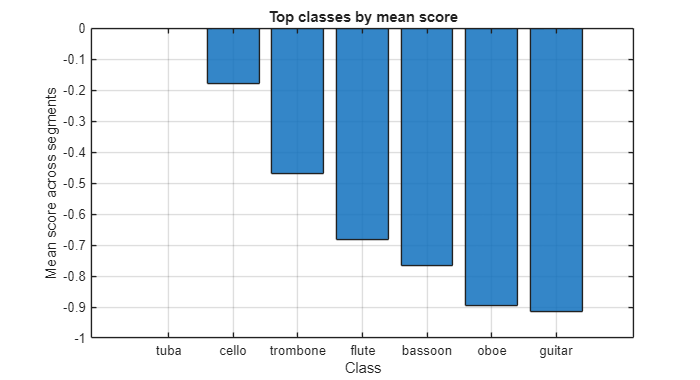

%% ========= 可视化每段置信度 =========
classNames = cellstr(uniqueLabels);   % 统一成 cellstr 方便画图
segTimes   = (starts-1)/fs;           % 每段起始时间（秒）
numSeg     = size(score,1);
[~, topIdxSeg] = max(score, [], 2);   % 每段最高分类别索引

% 1) 全局 Top-K 平均得分条形图
meanScore = mean(score, 1);                 % 1 x C
[meanScoreSorted, idxTop] = sort(meanScore, 'descend');
K = min(7, numel(idxTop));                  % 取所有类别或前 K
figure('Name','Mean class scores','Position',[100 100 700 380]);
bar(meanScoreSorted(1:K), 'FaceAlpha',0.85); grid on;
xticklabels(classNames(idxTop(1:K)));
ylabel('Mean score across segments'); xlabel('Class');
title('Top classes by mean score');

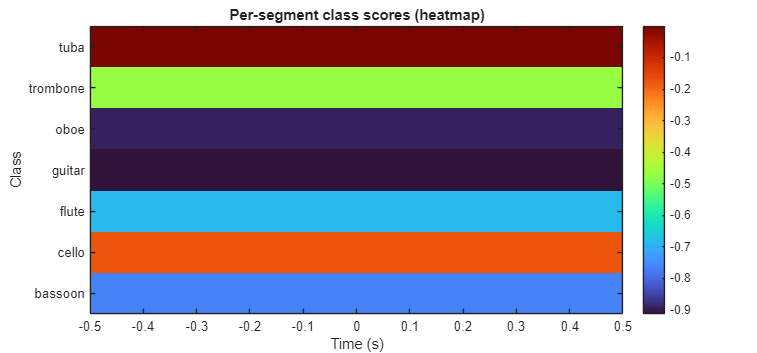


% 2) 段×类别热力图（置信度随时间/段变化）
figure('Name','Segment-class score heatmap','Position',[100 100 900 420]);
imagesc(segTimes, 1:numel(classNames), score');  % 转置后维度: 类 x 段
axis xy; colormap turbo; colorbar;
yticks(1:numel(classNames)); yticklabels(classNames);
xlabel('Time (s)'); ylabel('Class');
title('Per-segment class scores (heatmap)');

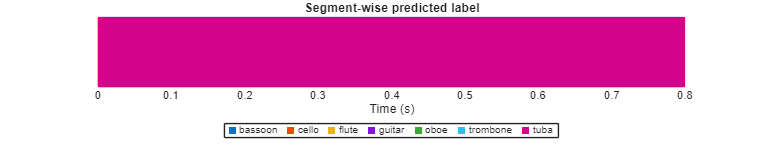


% 3) 时间轴上的段级预测（修复：每类不同颜色 + 正确图例）
figure('Name','Segment predictions over time','Position',[100 100 900 200]);
ax4 = gca; hold(ax4,'on');

% 以"每段预测标签 yp_batch"为准着色（而不是 max-score 的索引）
% yp_batch 在上面已转为 categorical；映射到类索引，0 表示未匹配（极少见）
[~, clsIdx] = ismember(yp_batch, categorical(classNames));

cmap = lines(numel(classNames));  % 给每个类别一套固定颜色
for i = 1:numSeg
    t0 = segTimes(i);
    t1 = t0 + (wlen/fs);
    k  = clsIdx(i); 
    if k == 0, k = 1; end   % 兜底，基本不会触发
    rectangle('Position', [t0 0 t1-t0 1], ...
              'FaceColor', cmap(k,:), 'EdgeColor', 'none', ...
              'Parent', ax4);
end

xlim(ax4, [segTimes(1), segTimes(min(numSeg,end)) + wlen/fs]);
ylim(ax4, [0 1]); yticks(ax4, []); box(ax4, 'on');
xlabel(ax4, 'Time (s)'); 
title(ax4, 'Segment-wise predicted label');

% 正确构造图例（每类一个独立句柄，避免全变同色）
K = numel(classNames);
ph = gobjects(K,1);
for k = 1:K
    ph(k) = plot(ax4, nan, nan, 's', ...
        'MarkerFaceColor', cmap(k,:), ...
        'MarkerEdgeColor', cmap(k,:), ...
        'MarkerSize', 8, ...
        'DisplayName', char(classNames(k)));
end
legend(ax4, ph, cellstr(classNames), ...
    'Location', 'southoutside', ...
    'NumColumns', min(7, K));



% 4) （可选）导出每段的预测与置信度到 CSV  —— 修正版
outCsv = fullfile('results','ml','demo_segment_scores.csv');
if ~isfolder(fileparts(outCsv)), mkdir(fileparts(outCsv)); end

% 排序列顺序（按均分从高到低）
[~, idx2] = sort(meanScore, 'descend');      % 1 x C 索引

% 4.1 元信息表（段号、起止时间、段预测）
Tmeta = table( (1:numSeg).', ...
               segTimes(:), ...
               segTimes(:) + wlen/fs, ...
               string(yp_batch(:)), ...
               'VariableNames', {'seg','t0','t1','pred'});

% 4.2 分数表（把 score 矩阵转成表，并命名每一列）
scoreNames = "score_" + string(classNames(idx2));      % string 数组
Tscore = array2table( score(:, idx2), ...
                      'VariableNames', cellstr(scoreNames) );

% 4.3 合并并写出
T = [Tmeta Tscore];
writetable(T, outCsv);
fprintf('Per-segment scores saved to: %s\n', outCsv);

Per-segment scores saved to: results\ml\demo_segment_scores.csv
